**NOTE : Requires Curve Fitting Tool**

Creation of the Interpolating Polinomial `WxFunctionZ(Z) `(to be done in preparation phase)

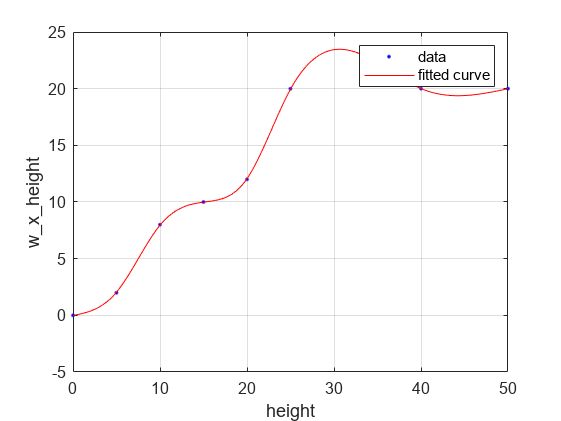

height = [0 5 10 15 20 25 40 50];
w_x_height = [0 2 8 10 12 20 20 20];

[xDataCurve, yDataCurve] = prepareCurveData( height, w_x_height );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 0.8;

% Fit model to data.
[WxFunctionZ, ~] = fit( xDataCurve, yDataCurve, ft, opts );

% Plotting
plot( WxFunctionZ, height, w_x_height );
% Label axes
xlabel( 'height', 'Interpreter', 'none' );
ylabel( 'w_x_height', 'Interpreter', 'none' );
grid on

Creation of Interpolating Surface `WyFunctionXY(X,Y) `(to be done in preparation phase)

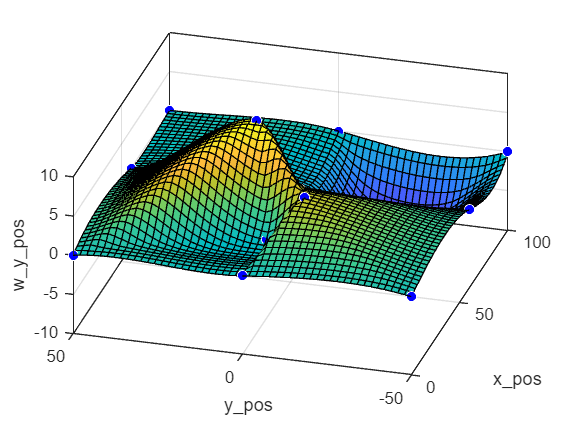

x_pos = [0,50,30,60,60,60,25,0,0,100,100,100,80];
y_pos = [0,10,-10,0,-50,50,0,-50,50,0,-50,50,-20];
w_y_pos = [0,10,5,0,0,0,0,0,0,0,0,0,-10];

[xDataSurf, yDataSurf, zDataSurf] = prepareSurfaceData( x_pos, y_pos, w_y_pos );

% Fit model to data.
[WyFunctionXY, ~] = fit( [xDataSurf, yDataSurf], zDataSurf, 'cubicinterp', 'Normalize', 'on' );

% Plotting
plot( WyFunctionXY, [xDataSurf, yDataSurf], zDataSurf );
% Label axes
xlabel( 'x_pos', 'Interpreter', 'none' );
ylabel( 'y_pos', 'Interpreter', 'none' );
zlabel( 'w_y_pos', 'Interpreter', 'none' );
grid on
view([-74.04 43.87])

Putting the 2 togheder in a 3D space with wind vectors

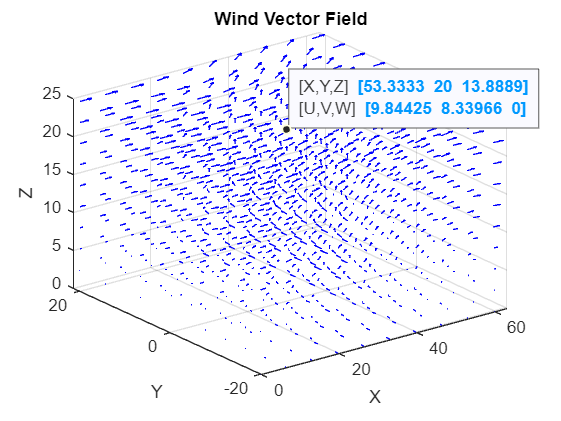

Nx = 10; % Number of points in X direction
Ny = 10; % Number of points in Y direction
Nz = 10; % Number of points in Z direction

[x_points, y_points, z_points] = meshgrid(linspace(0,60,Nx), linspace(-20,20,Ny), linspace(0,25,Nz));

% Creating wind vectors and populating (careful of limits)
WindVectors = zeros(Nx, Ny, Nz, 3);
for i = 1:Nx
    for j = 1:Ny
        for k = 1:Nz
            vx = WxFunctionZ(z_points(i,j,k));
            vy = WyFunctionXY(x_points(i,j,k), y_points(i,j,k));
            WindVectors(i,j,k,1) = vx; % x-component
            WindVectors(i,j,k,2) = vy; % y-component
        end
    end
end

% Plot
quiver3(x_points, y_points, z_points, WindVectors(:,:,:,1), WindVectors(:,:,:,2), WindVectors(:,:,:,3), 'b');
xlabel('X'), ylabel('Y'), zlabel('Z');
title('Wind Vector Field'), axis tight, grid on;